# Kids study plots examples 

This file provide example of the how to plot data from the kids study. 

This examples work when the data is organize by MakeSMatrixDM.m and concatenateMatrices.m 

Note: Most of the functions do not bellow to the labtools, they were written specifically for this data. This data was collected by Dr. Torres at Dr. Bastians lab.

## PLOT INDIVIDUAL AGE GROUPS

Type={'OG'}; %OG for overground data and TM for treadmill data 

Datalocation= cd

Datalocation = 'C:\Users\maris\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper'

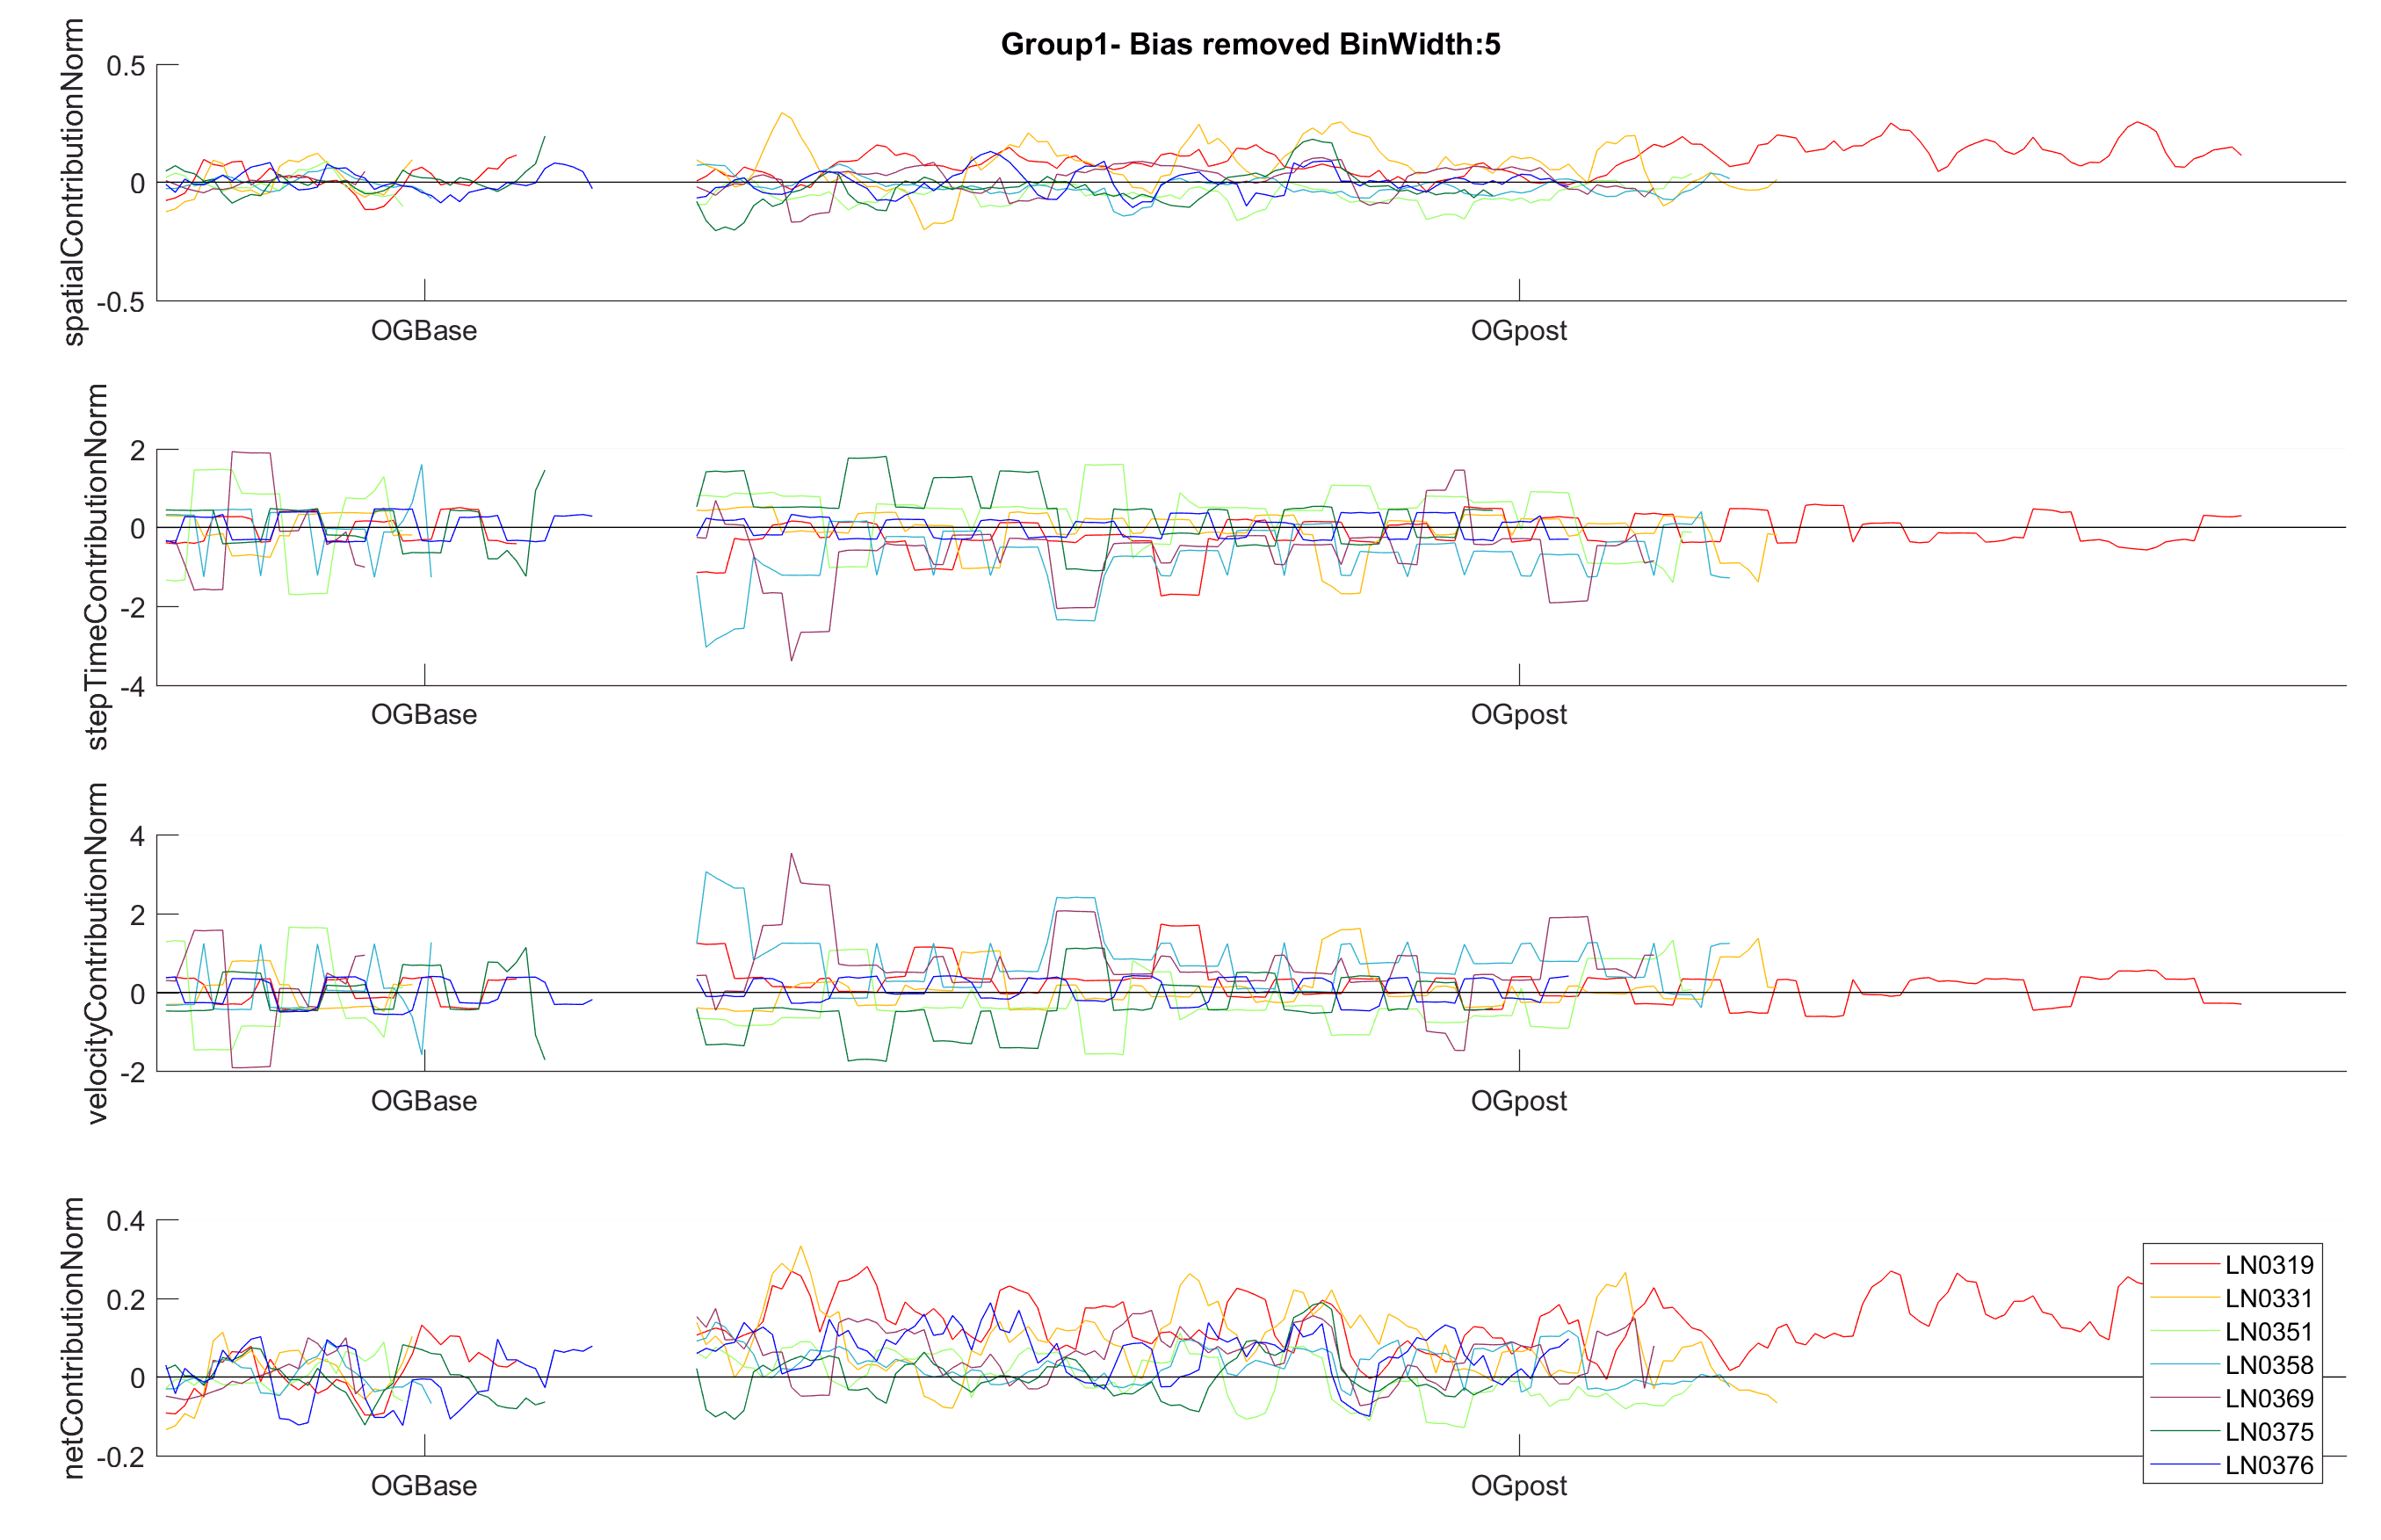

cd(['.\SMatrix\' Type{1} 'SMatrix\Line'])

% cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix\Line'])%data localization
 
files=what('./'); 
fileList=files.mat;

for i=1 %i represent the groups that you want to plot 
group=num2str(fileList{i});
load(group)

binwidth=5;
removeBias=1;
indvplot=1;
parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};

if strcmp(Type,'OG')
cond={'OGBase','OGpost'};
else
cond={'TMBase','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};
end


TimecourseDM(SMatrix,parameters,cond,binwidth,indvplot,removeBias);

end 


cd(Datalocation)




## PLOT AVG GROUPS

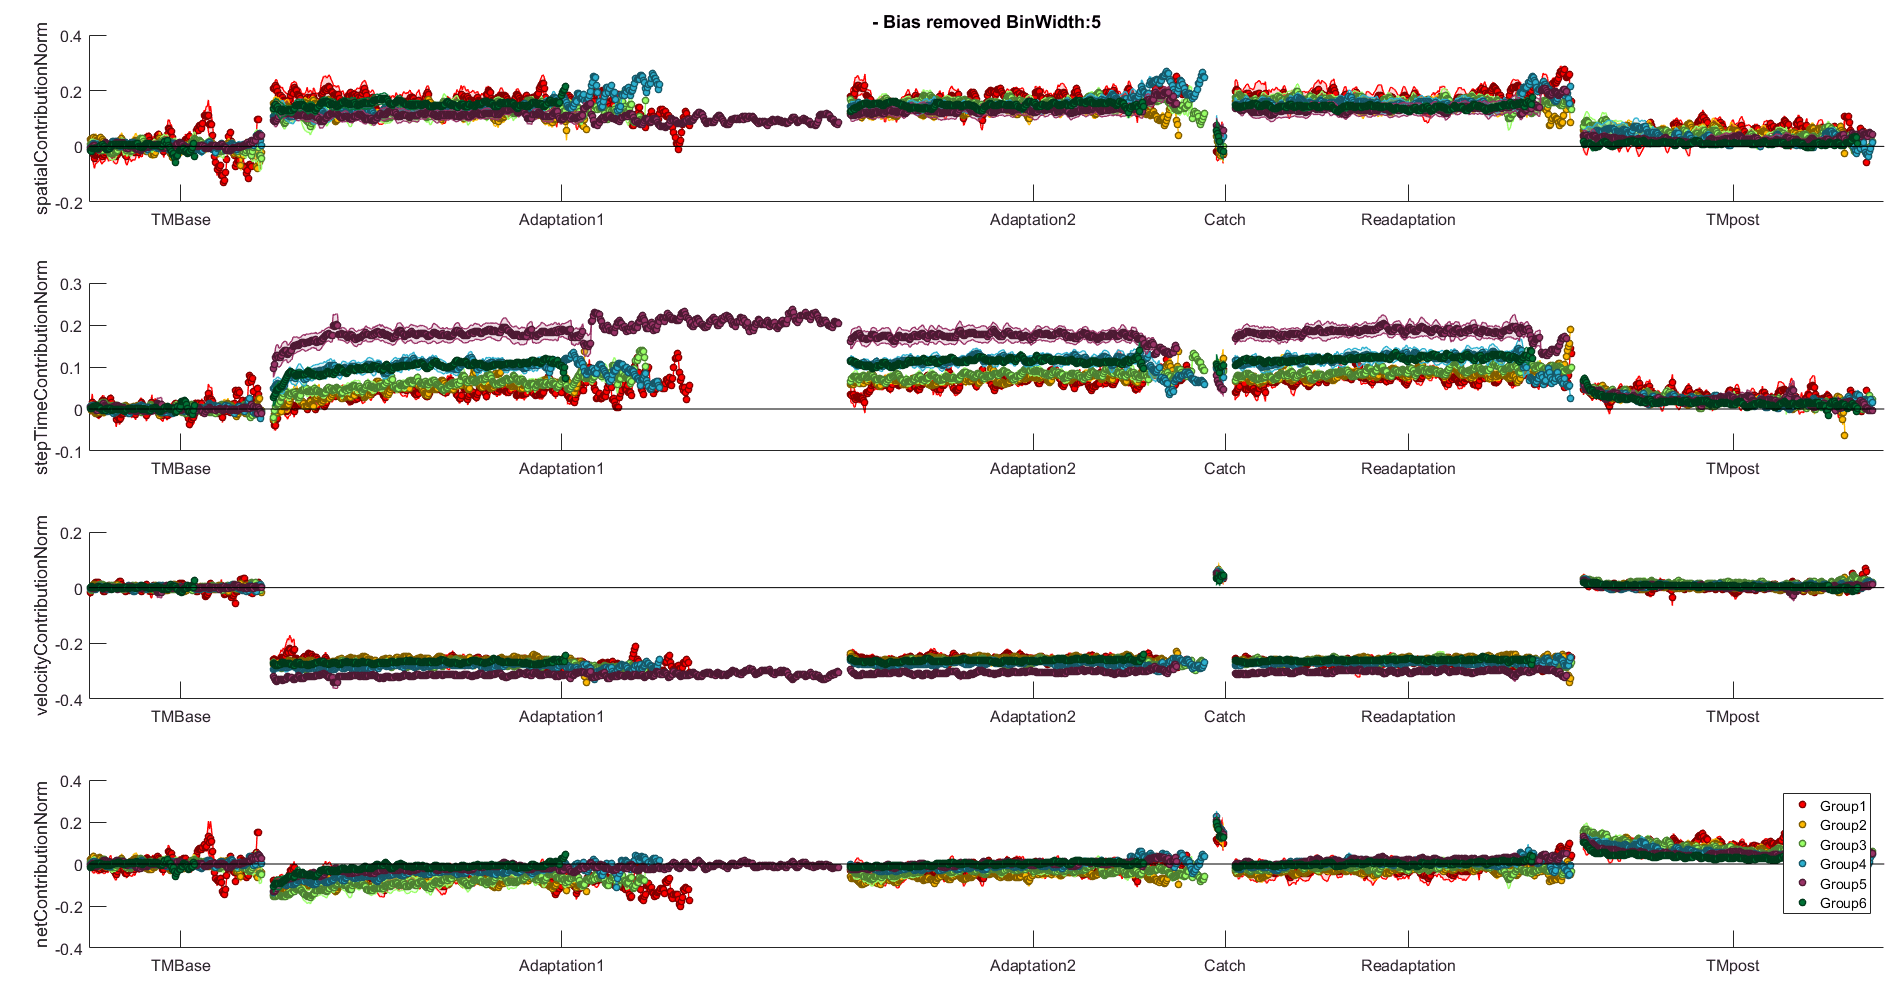


Type={'TM'};  %OG for overground data and TM for treadmill data 

cd(['C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\' Type{1} 'SMatrix'])

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{1});
load(group)

%Inputs that can be modify 
binwidth=5;
removeBias=1;
parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};

if strcmp(Type,'OG')
cond={'OGBase','OGpost'};
else
cond={'TMBase','Adaptation1','Adaptation2','Catch','Readaptation','TMpost'};

end

TimecourseDM(SMatrix,parameters,cond,binwidth,0,removeBias);

## ALL CONDITIONS INDIVIDUAL AGE GROUP TIME COURSE

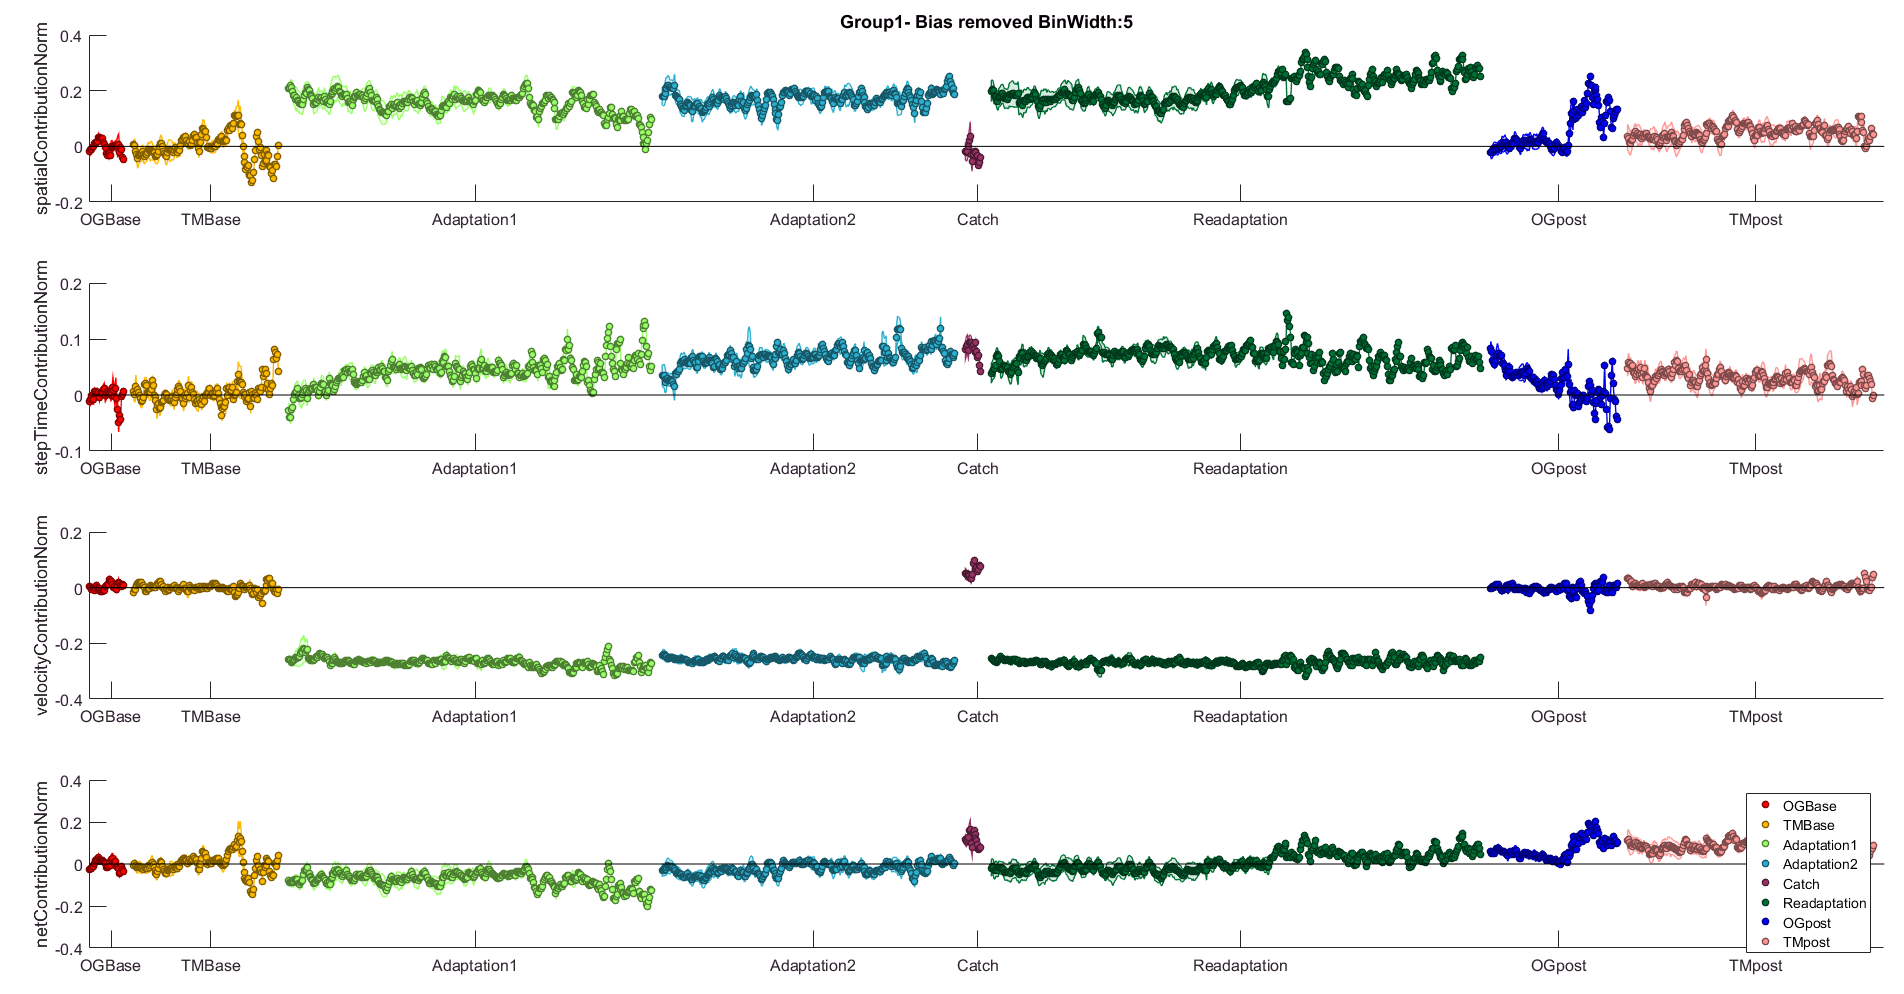

cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll\Groups')

files=what('./'); 
fileList=files.mat;

for i=1  %i represent the groups that you want to plot 
    
group=num2str(fileList{i});
load(group)

%Inputs that can be modify 
binwidth=5;
removeBias=1;
indvplot=0;


parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};


cond={'OGBase','TMBase','Adaptation1','Adaptation2','Catch','Readaptation','OGpost','TMpost'};

TimecourseDM(ConcMatrix,parameters,cond,binwidth,indvplot,removeBias);

end

## ALL CONDITION ALL GROUPS TIME COURSE

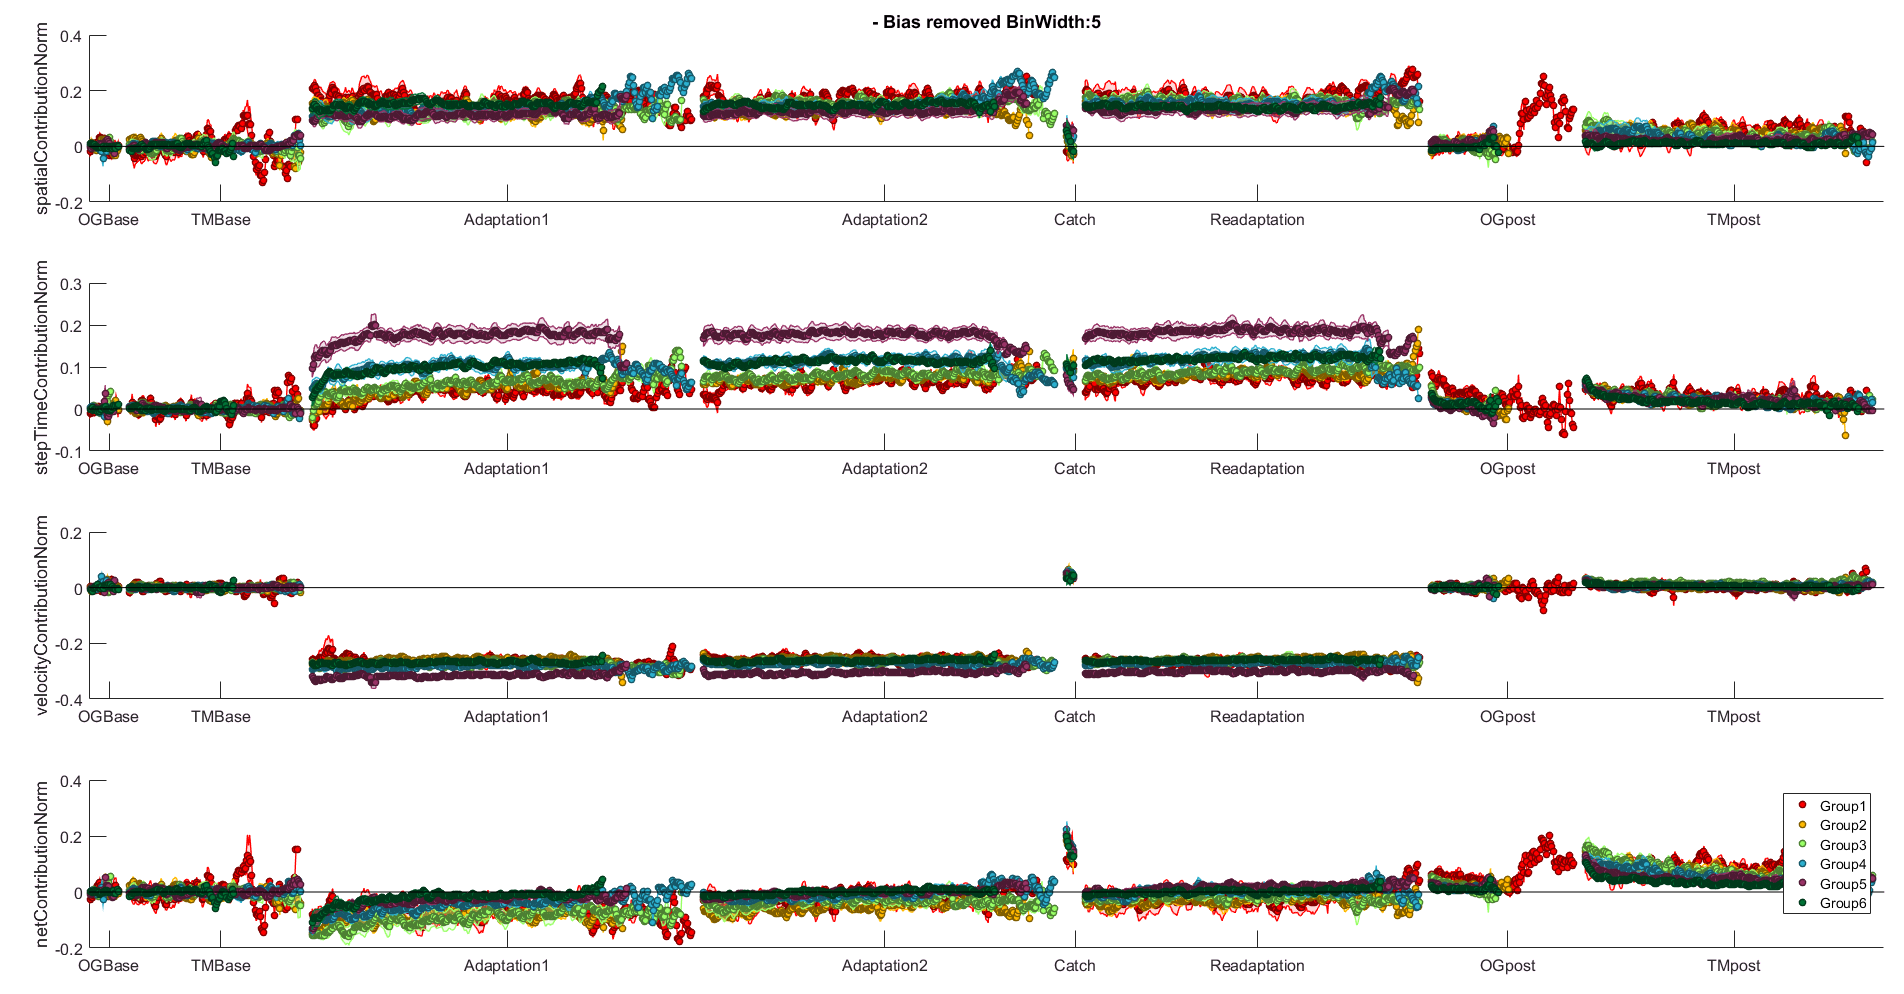


cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLineAll')

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{1});
load(group)
binwidth=5;
removeBias=1;

parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};

cond={'OGBase','TMBase','Adaptation1','Adaptation2','Catch','Readaptation','OGpost','TMpost'};


TimecourseDM(ConcMatrix,parameters,cond,binwidth,0,removeBias);

##  BAR PLOT RESULTS 

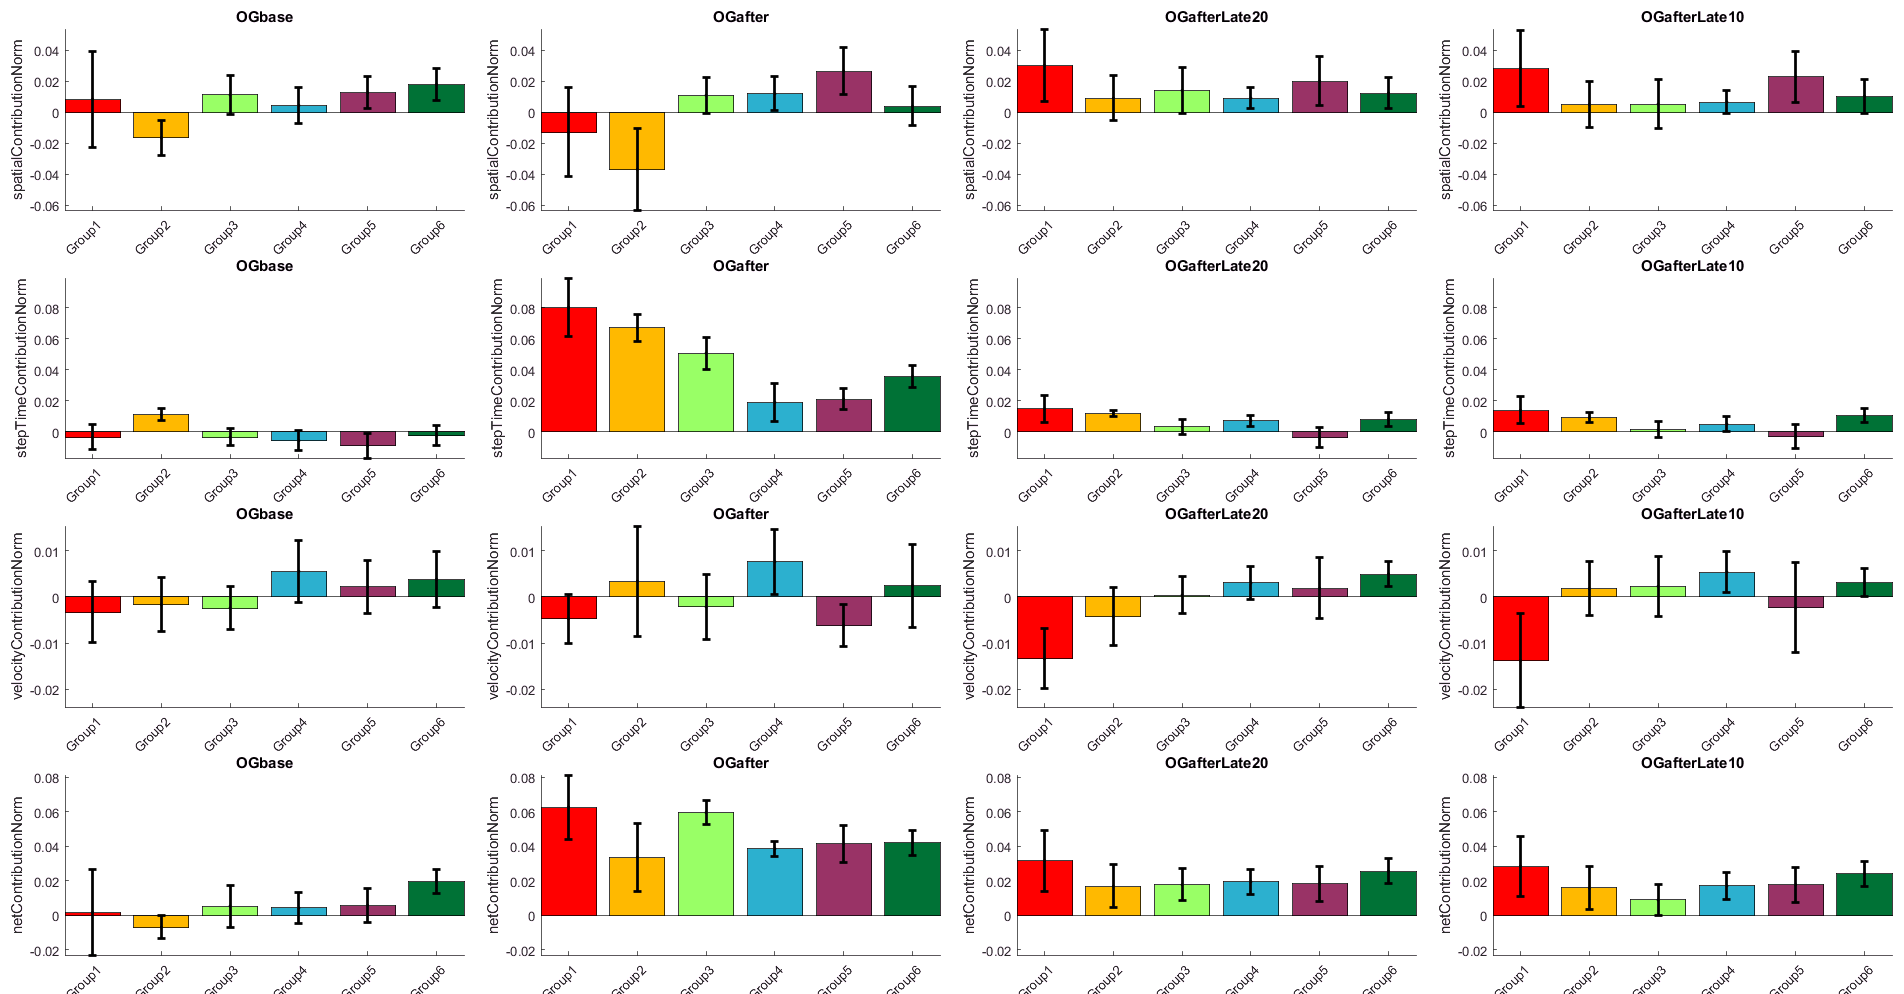


cd('C:\Users\dum5\OneDrive - University of Pittsburgh\KidsStudy\Data\Kids_paper\SMatrix\ConcSMatrixLine')

files=what('./'); 
fileList=files.mat;

group=num2str(fileList{1});
load(group)

removeBias=0;
maxPerturb=0;
indivFlag=0;
plotFlag=1; %if you want to get a plot plotFlag most be 1

parameters={'spatialContributionNorm','stepTimeContributionNorm','velocityContributionNorm','netContributionNorm'};
cond={'OGBase', 'TMBase','Adaptation1','Catch','Readaptation','OGpost','TMpost','Adaptation2'};

results = getResultsDM(ConcMatrix,parameters,[],maxPerturb,plotFlag,indivFlag,removeBias,cond);